%7. Considere um processo de produc¸ao fabril que produz torneiras em que a probabilidade de cada torneira ˜
%ser produzida com defeito e de 30%. No processo de controlo de qualidade, ´ e selecionada uma amostra ´
%de 5 pec¸as.
%(a) Calcule analiticamente e por simulac¸ao a probabilidade de 3 pec¸as da amostra serem defeituosas. 

%Por simulação
%% N = numero de experiencias
%% p = probabilidade de caras
%% k = numero de caras
%% n = numero de lançamentos
N = 1e5;
n = 5;
p = 0.3;
k = 3;
lancamentos = rand(n,N) <= p;        %% a probabilidade de uma peça ser defeituosa nunca é maior que 30%
sucessos = sum(lancamentos) == k;
probSimulacao = sum(sucessos)/N

probSimulacao = 0.1307


%Analiticamente
prob = nchoosek(n,k)*p^k*(1-p)^(n-k)

prob = 0.1323


%%(b) Calcule analiticamente e por simulac¸ao a probabilidade de, no m ˜ aximo, 2 das pec¸as da amostra serem ´
%defeituosas.


k = 2;
lancamentos = rand(n,N) <= p;
sucessos = sum(lancamentos) <= k;
probSimulacao1 = sum(sucessos)/N

probSimulacao1 = 0.8378


prob1 = nchoosek(n,k)*p^k*(1-p)^(n-k)

prob1 = 0.3087

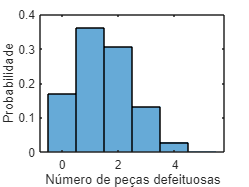

%(c) Baseado em simulac¸ao, construa no Matlab o histograma representativo da distribuic¸ ˜ ao de probabili- ˜
%dades do numero de pec¸as defeituosas da amostra.
%histograma para peças defeituosas

lancamentos = rand(n,N) <= p;
num_defeituosas = sum(lancamentos);

histogram(num_defeituosas,'Normalization','probability');
xlabel('Número de peças defeituosas');
ylabel('Probabilidade');%(b) Calcule analiticamente e por simulac¸ao a probabilidade de, no m ˜ aximo, 2 das pec¸as da amostra serem ´

%defeituosas.
